# Demo Fast Gaussian Simulation

## Simple 2D 

Define the simulation parameters

sim.s=[100 100]; % simulation size 
sim.n=6; % number of simulation
sim.DisplayProgression=true; % Display a progression bar

Define the covariance parameters

covar.model = 'k-bessel'; % type of covariance function, see covarIni.m for option
covar.range0 = [4 4]; % range of covariance, vector same size as sim.s.
covar.azimuth = 0; % orientation of the covariance
covar.c0 = 1; % variance
covar.alpha = 5; % parameter of covariance function (depend on the model chosen, see covarIni.m for option)

Compute

tic; res = FGS(sim,covar);toc

Elapsed time is 1.923972 seconds.


Display result

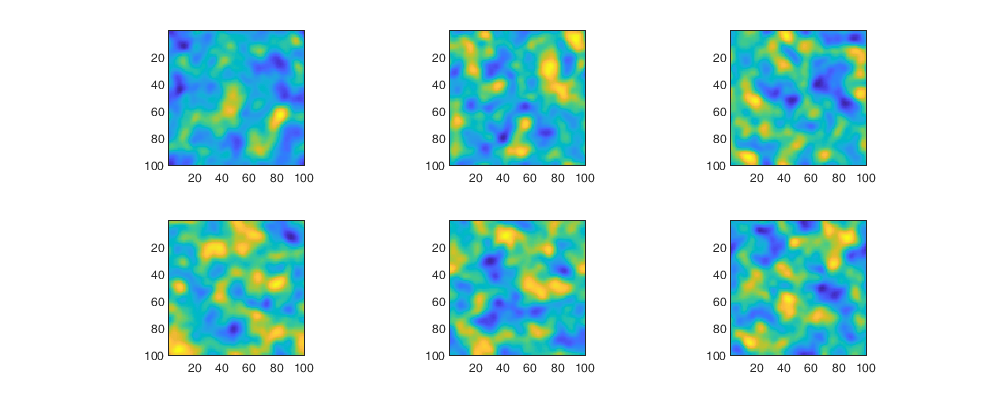

figure('position',[0 0 1000 400]); 
for i=1:sim.n
    subplot(ceil(sim.n/ceil(sqrt(sim.n))),ceil(sqrt(sim.n)), i)
    imagesc(res{i}); axis equal tight;
end

## 3D simulations

sim.s=[100 100 100];
sim.n = 1;
covar.model = 'k-bessel';
covar.range0 = [20 40 10];
covar.azimuth = [0 0];
covar.c0 = 3;
covar.alpha = 5;

tic;res = FGS(sim,covar);toc;

Elapsed time is 97.144208 seconds.


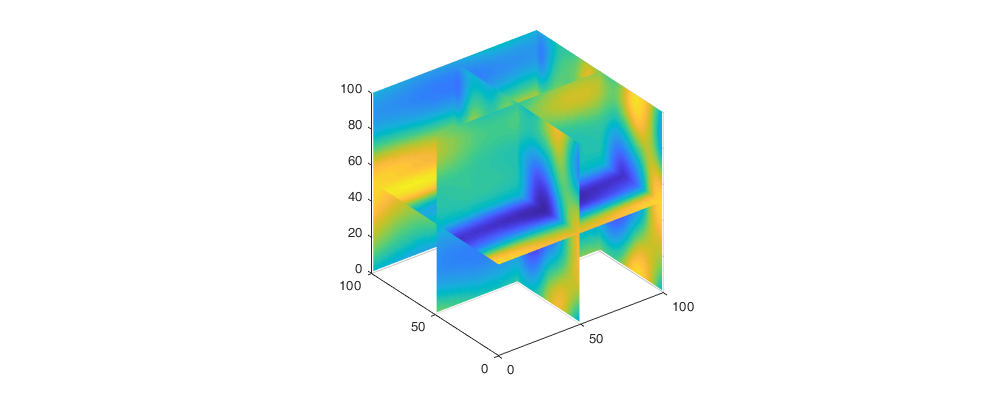

figure('position',[0 0 1000 400]); 
for i=1:sim.n
    subplot(ceil(sim.n/ceil(sqrt(sim.n))), ceil(sqrt(sim.n)), i)
    s=slice(res{i},0:50:100,0:50:100,[0 50]);
    axis equal
    set(s,'edgecolor','none')
end